# **Matlab homework (lab 2)**

 clear; close all;
% insert your names and IDs here
Name{1} = 'Pere Quílez Codina';
NIA{1} = 240446;
Name{2} = 'Nicolás Vila';
NIA{2} = 240230;

% ALSO : Do not use make additional calls to "clear all;" between steps.




## load file from .mat


load Dataset.mat

n= 5504; %número de observaciones
k=2; %número de variables

# QUESTION 2

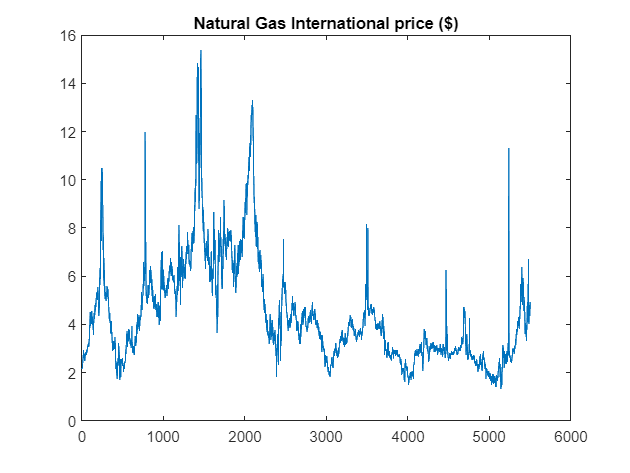

% Enter code for question 2 here

%Creamos las matrices para almacenar los datos y realizar las operaciones
X_1 = ones(n,1); 
X_2 = ones(n,1);
Y = ones(n,1);
N = ones(n,1);

for i=1:n
    X_1(i)= (Dataset.NatGas(i));
    X_2(i)= log(Dataset.SP500(i)); %Aplicamos log porque vemos que los datos de esta variable crecen exponencialmente
    Y(i)= (Dataset.InterestRates(i));
    N(i)=i;
end

plot(N,X_1);
title('Natural Gas International price ($)');

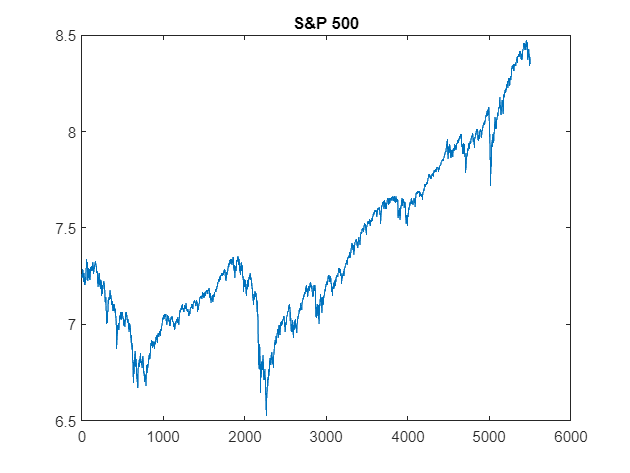


plot(N,X_2);
title('S&P 500');

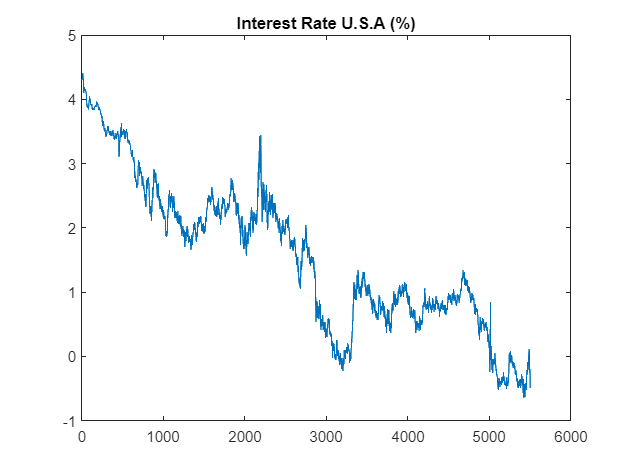


plot(N,Y);
title('Interest Rate U.S.A (%)');


%x_2
%y
X=[ones(n,1), X_1, X_2]; %creamos matrix X

X_T=transpose(X);

B=(inv(X_T*X))*(X_T*Y);%normal equation

b0=B(1,1)

b0 = 14.7231

b1=B(2,1)

b1 = 0.0619

b2=B(3,1)

b2 = -1.8196

n_2=round(n/6)

n_2 = 917

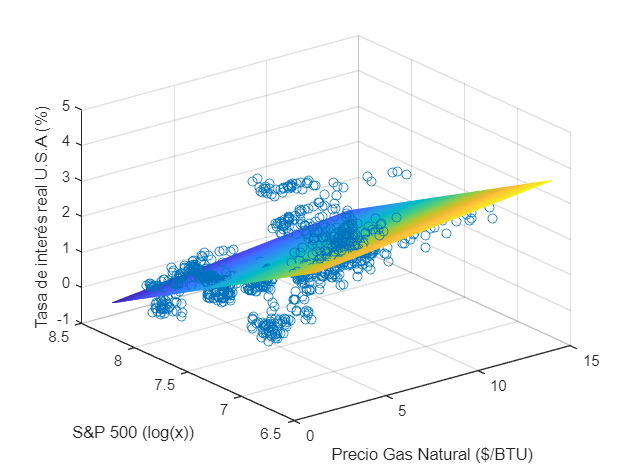

x_1 = ones(n_2,1);
x_2 = ones(n_2,1);
y = ones(n_2,1);


%Para graficar los datos con el plano utilizamos solo 1/6 de los datos ya
%que son demasiados para hacer el plot con todos (no carga)
for i=6:6:n
    a=round(i/6);
    x_1(a)= Dataset.NatGas(i);
    x_2(a)= log(Dataset.SP500(i));
    y(a)= Dataset.InterestRates(i);
    
end
[x1,x2]=meshgrid(x_1,x_2);
Y_P=b0+b1.*x1+b2.*x2;
scatter3(x_1,x_2,y);
xlabel('Precio Gas Natural ($/BTU)')
ylabel('S&P 500 (log(x))')
zlabel('Tasa de interés real U.S.A (%)')
hold on
mesh(x1,x2,Y_P);
hold off

La forma que toma la solución de la regresión lineal con 2 variables es un plano de la forma Y = b0 + b1*X_1 + b2*X_2 de manera que represente de la mejor manera posible todo el conjunto de datos.

# QUESTION 3

% write your code here code
y_predicted= X*B;

mean_y=mean(Y);
mean_Y=ones(n,1)*mean_y;
%Cálculo de SS_REG
SS_REG=(y_predicted-mean_Y).*(y_predicted-mean_Y);
SS_REG=sum(SS_REG,1)

SS_REG = 3.9486e+03


%Cálculo de SS_ERR
SS_ERR=(Y-y_predicted).*(Y-y_predicted);
SS_ERR=sum(SS_ERR,1)

SS_ERR = 3.5119e+03

SS_TOT=SS_REG+SS_ERR

SS_TOT = 7.4605e+03


%Cálculo de MS_REG
MS_REG=SS_REG/k

MS_REG = 1.9743e+03


%Cálculo de MS_ERR
MS_ERR=SS_ERR/(n-k-1)

MS_ERR = 0.6384


%Cálculo del estadístico F
F=MS_REG/MS_ERR

F = 3.0925e+03


%Cálculo del coeficiente de determinación
R_2=SS_REG/SS_TOT

R_2 = 0.5293


%Intervalo de aceptación
X_aux=inv(X_T*X);
finv(0.95,k,n-k-1)

ans = 2.9974

% obtenemos un intervalo de aceptación de (0, 2.997) mientras que nuestro
% estadístico nos da un resultado de 3000 aproximadamente por lo que
% podemos rechazar la hipótesis nula y afirmar que nuestro modelo explica
% parte de la variancia de los datos(ya que cae fuera de la región de aceptación). Esto lo afirma también el coeficiente
% de detrminación que es de 52.9% lo que indica que más de la mitad de
% la variancia de los datos los explica el modelo de regresión lineal.

%P Valor
P = 1- fcdf(F,k,n-k-1)

P = 0

% Observamos que el valor p para el test de Fisher es 0. Esto es, para tal
% de aceptar la hipótesis nula, alpha debería de ser 0 or lo que concluimos
% que rechazamos sobradamente la hipotesis nula

# QUESTION 4

% Ahora realizaremos un test para averiguar si cada una de las variables x1
% y x2 tienen efecto en nuestro modelo. Para ello realizaremos dos tests de
% t de Student(uno para b1 y otro para b2)
%valor t de b1

t_1=b1/(sqrt(MS_ERR*X_aux(2,2)))

t_1 = 11.4006

%valor t de b2

t_2=b2/(sqrt(MS_ERR*X_aux(3,3)))

t_2 = -66.9706

%Calculamos el intervalo de aceptación en el test t de Student y como es una distribución simétrica, 
% A = (-1.9604, 1.9604). Los valores t de b1 y b2 caen fuera de este
% intervalo por lo que rechazaríamos la hipótesis nula. Para reafirmarlo,
% calculamos los valores p.

tinv((0.95+0.05/2),n-k-1)

ans = 1.9604

%valor p per b1
%Multiplicamos por 2 porque es un test de doble cola.
P_b1 = (1- tcdf(t_1,n-k-1))*2 

P_b1 = 0


%valor p per b2
%Multiplicamos por 2 porque es un test de doble cola.(valor absoluto para que no se calcule con valores negativos)
P_b2 = (1-tcdf(abs(t_2),n-k-1))*2 

P_b2 = 0

% Observamos que el valor p para ambos tests es de 0 por lo que
% argumentando o mismo que en el test F, podemos rechazar holgadamente la
% hipótesis nula ya que alpha debería de ser prácticamente 0 para aceptarla
% lo cual no tiene sentido. Con todo, concluimos que tanto b1 como b2
% tienen un efecto significativo en el modelo.